# Markov Chain Monte Carlo (MCMC)

clear; clc;
cd('/Users/duncan/Documents/GitHub/Advanced-Biomedical-Experimental-Design-and-Statistics/Markov Chain Monte Carlo (MCMC)')

## Monte Carlo

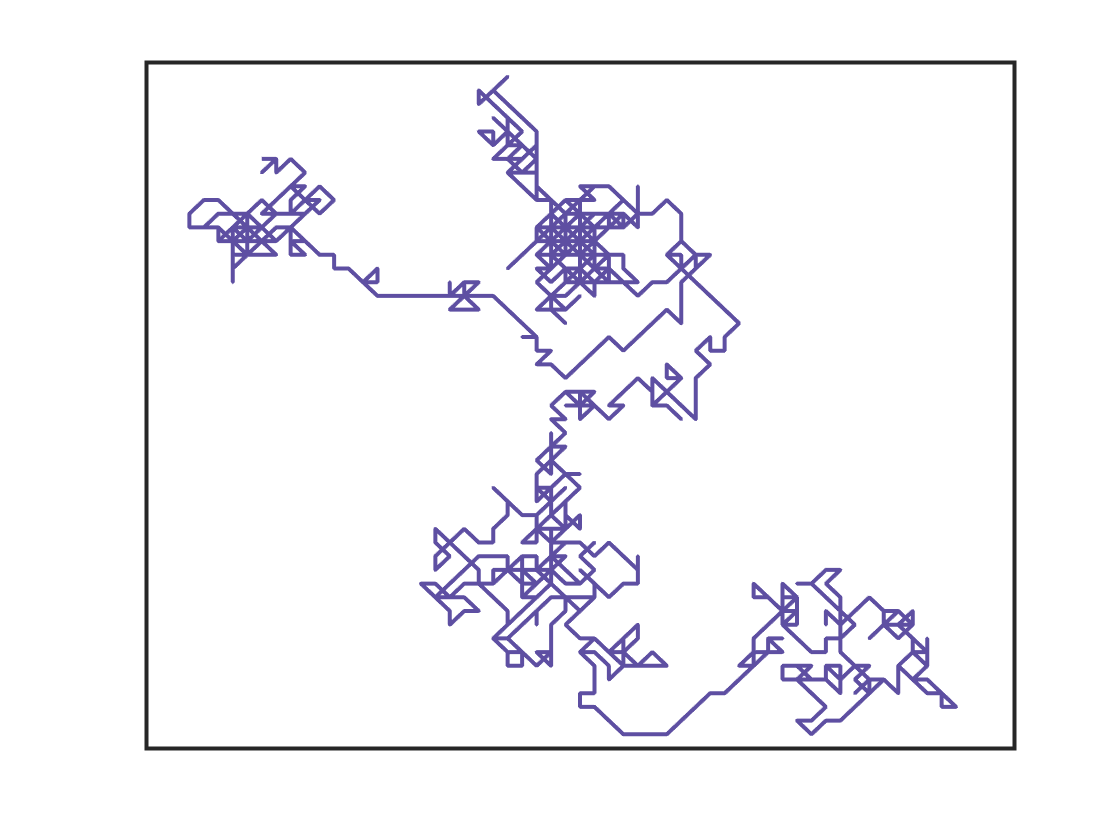

nSteps = 1e3;
walk = nan(nSteps, 2);
walk(1,:) = [-2,-2];
directions = -1:1:1; 
for iStep = 2:nSteps
    direction = datasample(directions, 2, 'replace', true); 
    walk(iStep,:) = walk(iStep-1,:) + direction;
end


figure();
plot(walk(:,1), walk(:,2))
xticks([]); 
yticks([]);

## Gibbs Sampling - Binomial Distribution

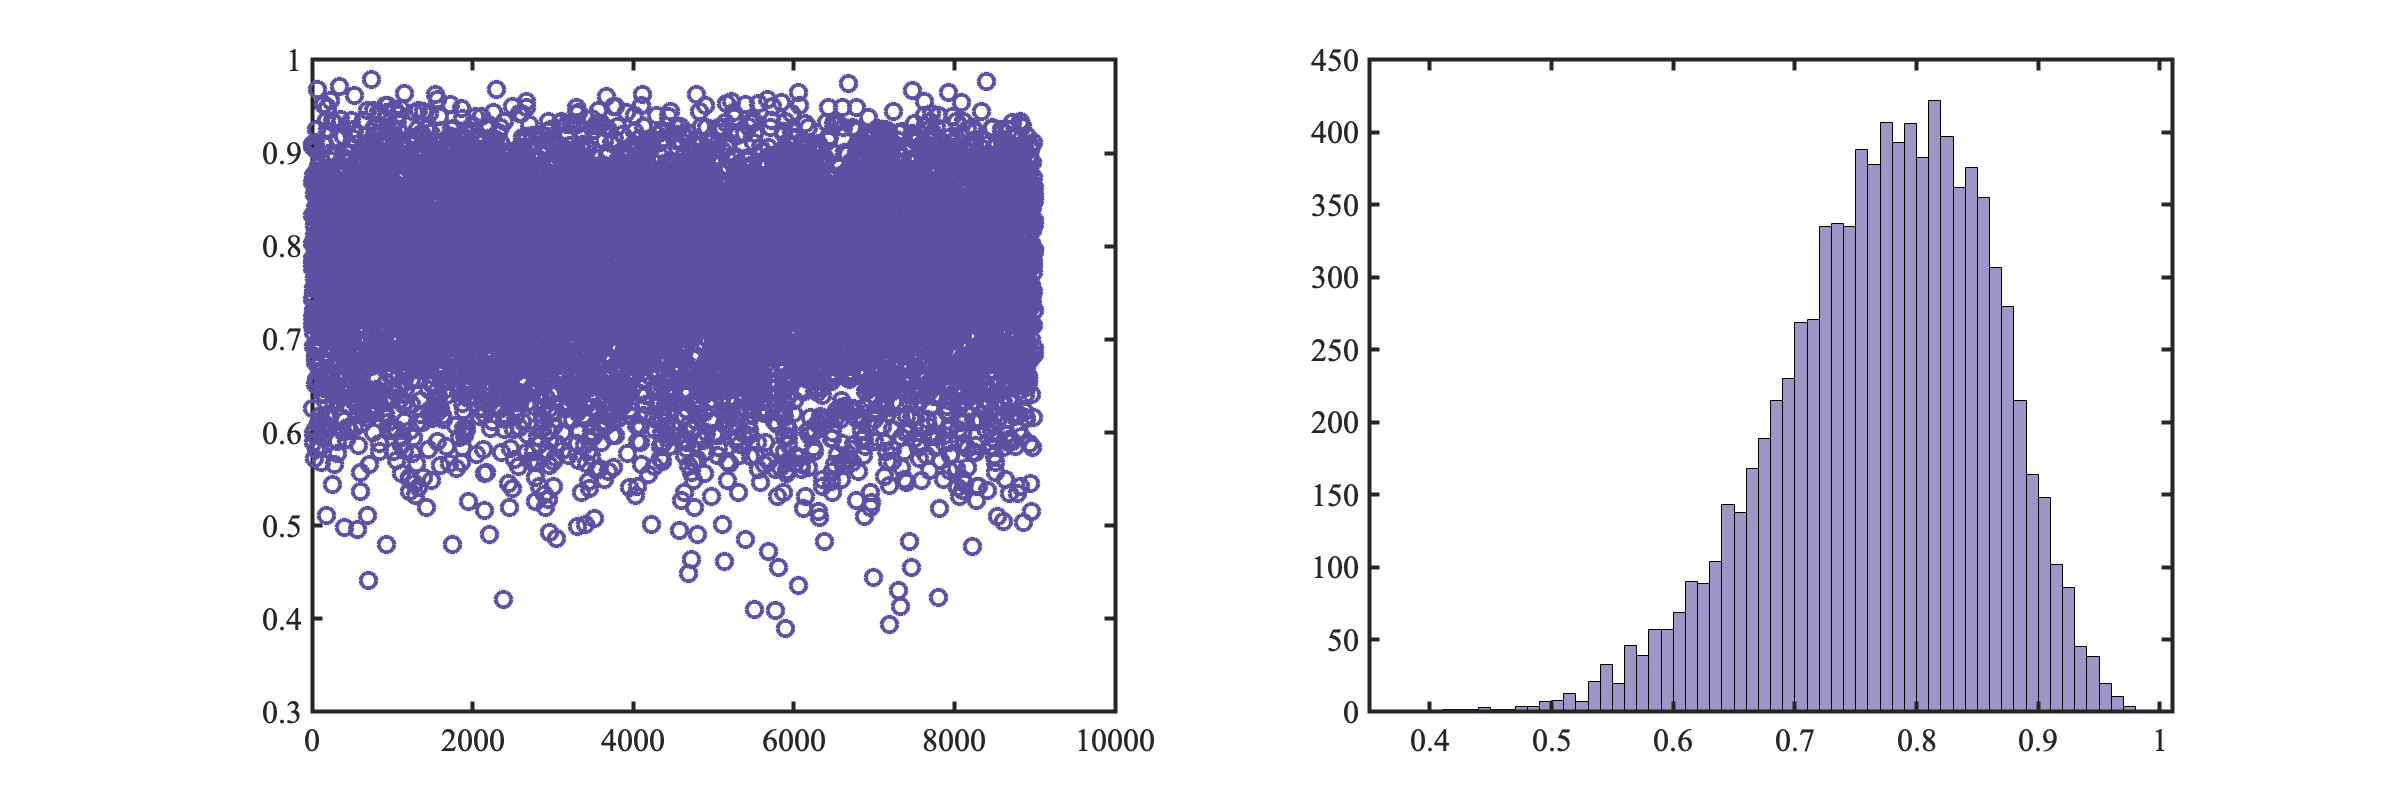

K = 16;
N = 20;
n = 10000; % number of samples to perform
alpha = 1;
beta = 1;
WEIGHT = nan(n,1); 
WEIGHT(1) = 0.5; 
burn = 1000; % burn in period
for i = 1:n
    WEIGHT(i) = betarnd((K+alpha), (N-K+beta), 1);
end

figure('position', [300 300 1200 400]);

subplot(1,2,1);
plot(WEIGHT(burn:end), 'o', 'markersize', 8);

subplot(1,2,2);
histogram(WEIGHT(burn:end));

## Gibbs Sampling - Normal Distribution

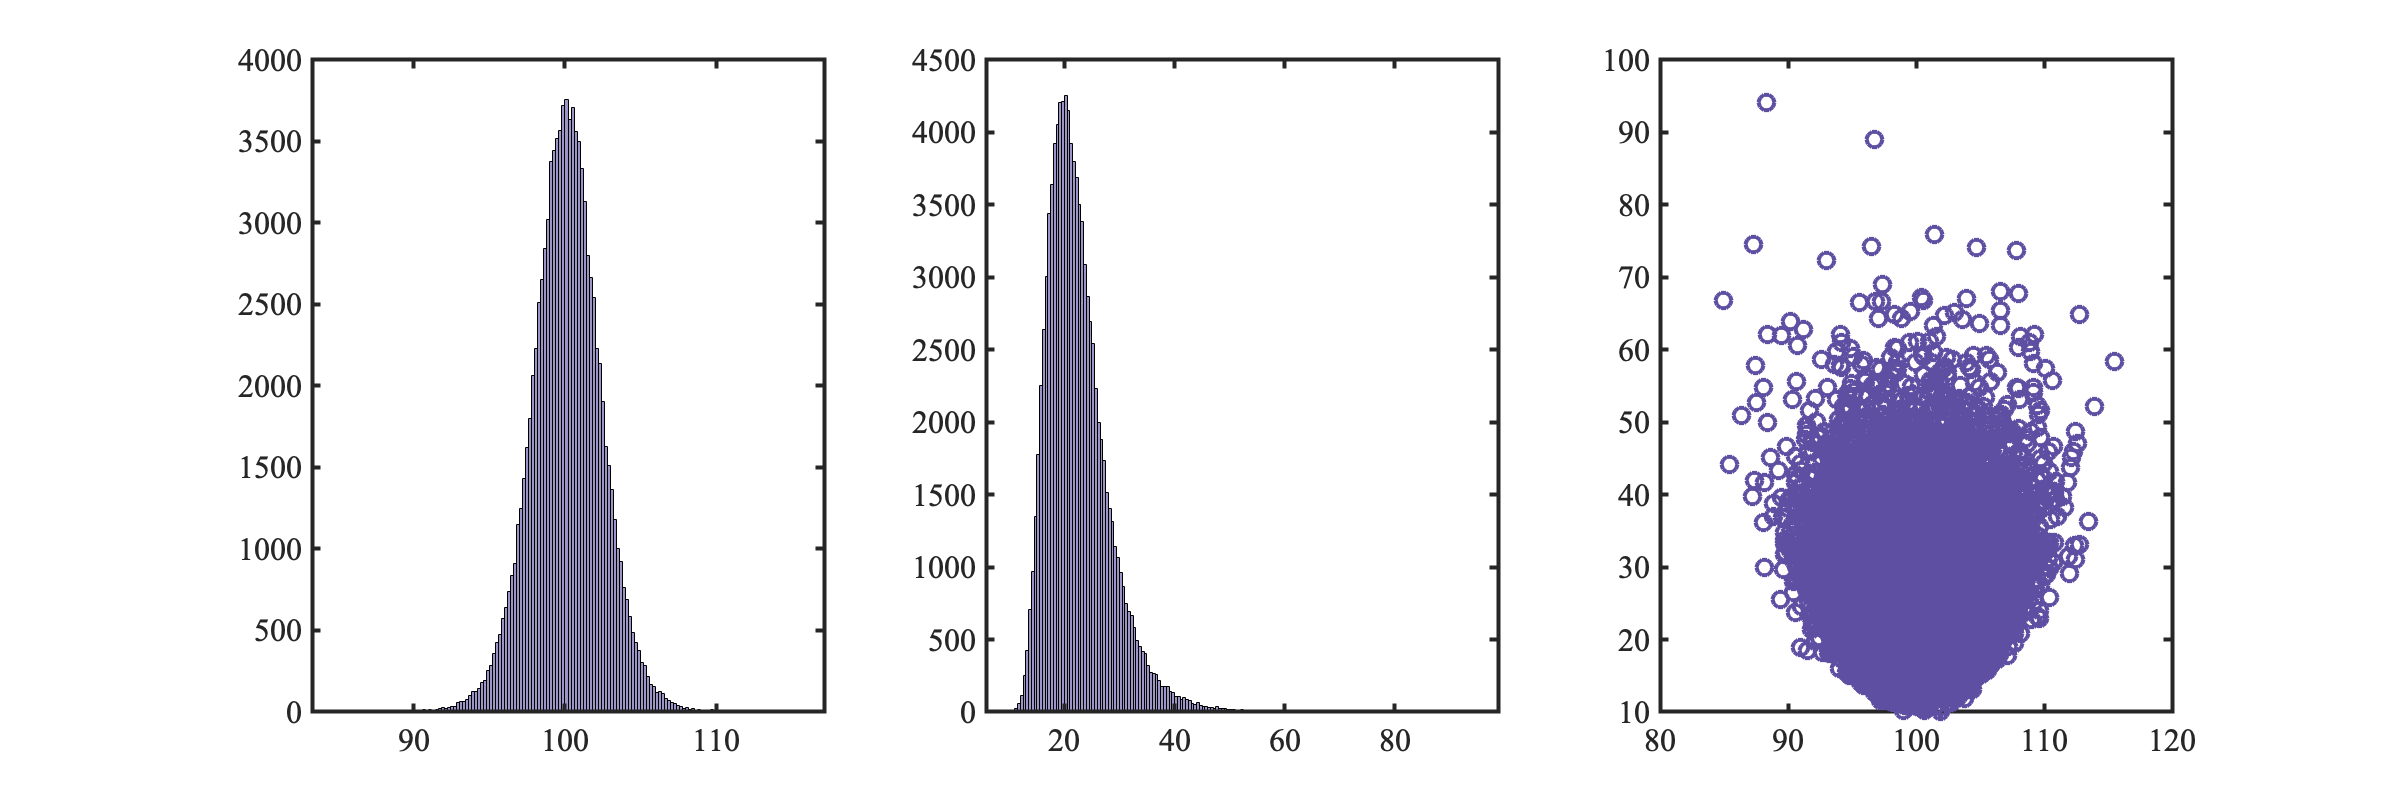

x = [105.01510, 97.05776, 106.70943, 98.73814, 95.81697, 92.36068, 76.02600, 112.06383, 109.26824, 108.18182];
n = 100000; % number of samples to perform
MU = nan(n,1); % initialize arrays
SIGMA = nan(n,1); 
MU(1) = 90; % initial guess
SIGMA(i) = 5; 

for i = 2:n
    SIGMA(i) = sqrt(1 / gamrnd(length(x) / 2, 1 / sum((x - MU(i-1)).^2) / 2)); 
    MU(i) = normrnd(mean(x),SIGMA(i)/length(x)); 
end

figure('position', [300 300 1200 400]); 

subplot(1,3,1);
histogram(MU(burn:end));
 
subplot(1,3,2);
histogram(SIGMA(burn:end));

subplot(1,3,3);
plot(MU(burn:end), SIGMA(burn:end), 'o', 'markersize', 8); 

MUmod = mode(MU(burn:end))

MUmod = 84.9715

SIGmod = mode(SIGMA(burn:end))

SIGmod = 10.1318

## Gibbs Sampling - Plots

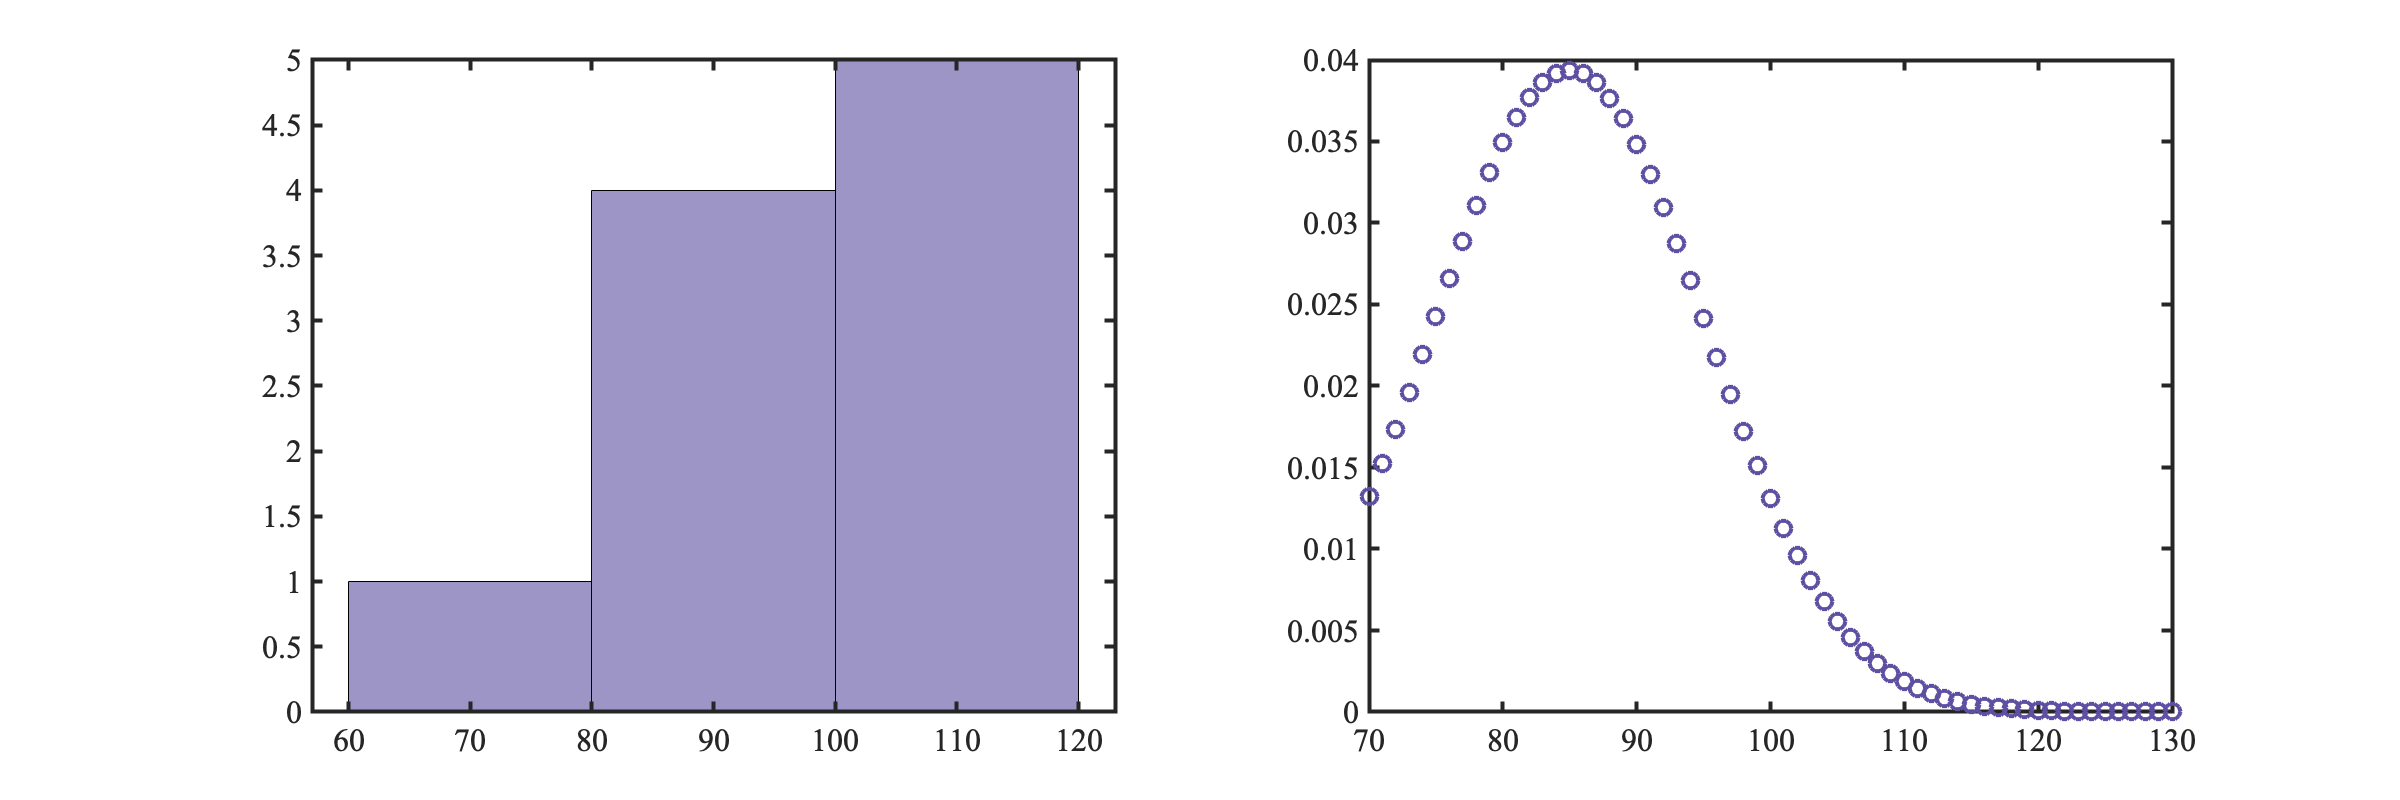

x1 = 70:130;
pdfx = (1/(SIGmod * sqrt(2 * pi))) * exp(-0.5 * ((x1 - MUmod)/SIGmod).^2);

figure('position', [300 300 1200 400]);

subplot(1,2,1);
histogram(x);

subplot(1,2,2);
plot(x1, pdfx, 'o', 'markersize', 8)

## Metropolis-Hastings - Example

n = 100000;
current = 0.5; % Initial guess of w
samps = nan(n,1); 
for i = 1:n
    proposed = normrnd(current, 0.4); % tuning parameter is 0.4
    logr = log_q(proposed)-log_q(current);
    if log(rand) <= logr
        current = proposed;
    end
    samps(i) = current;
end
acc_rate = length(unique(samps))/n % acceptance rate

acc_rate = 0.2583

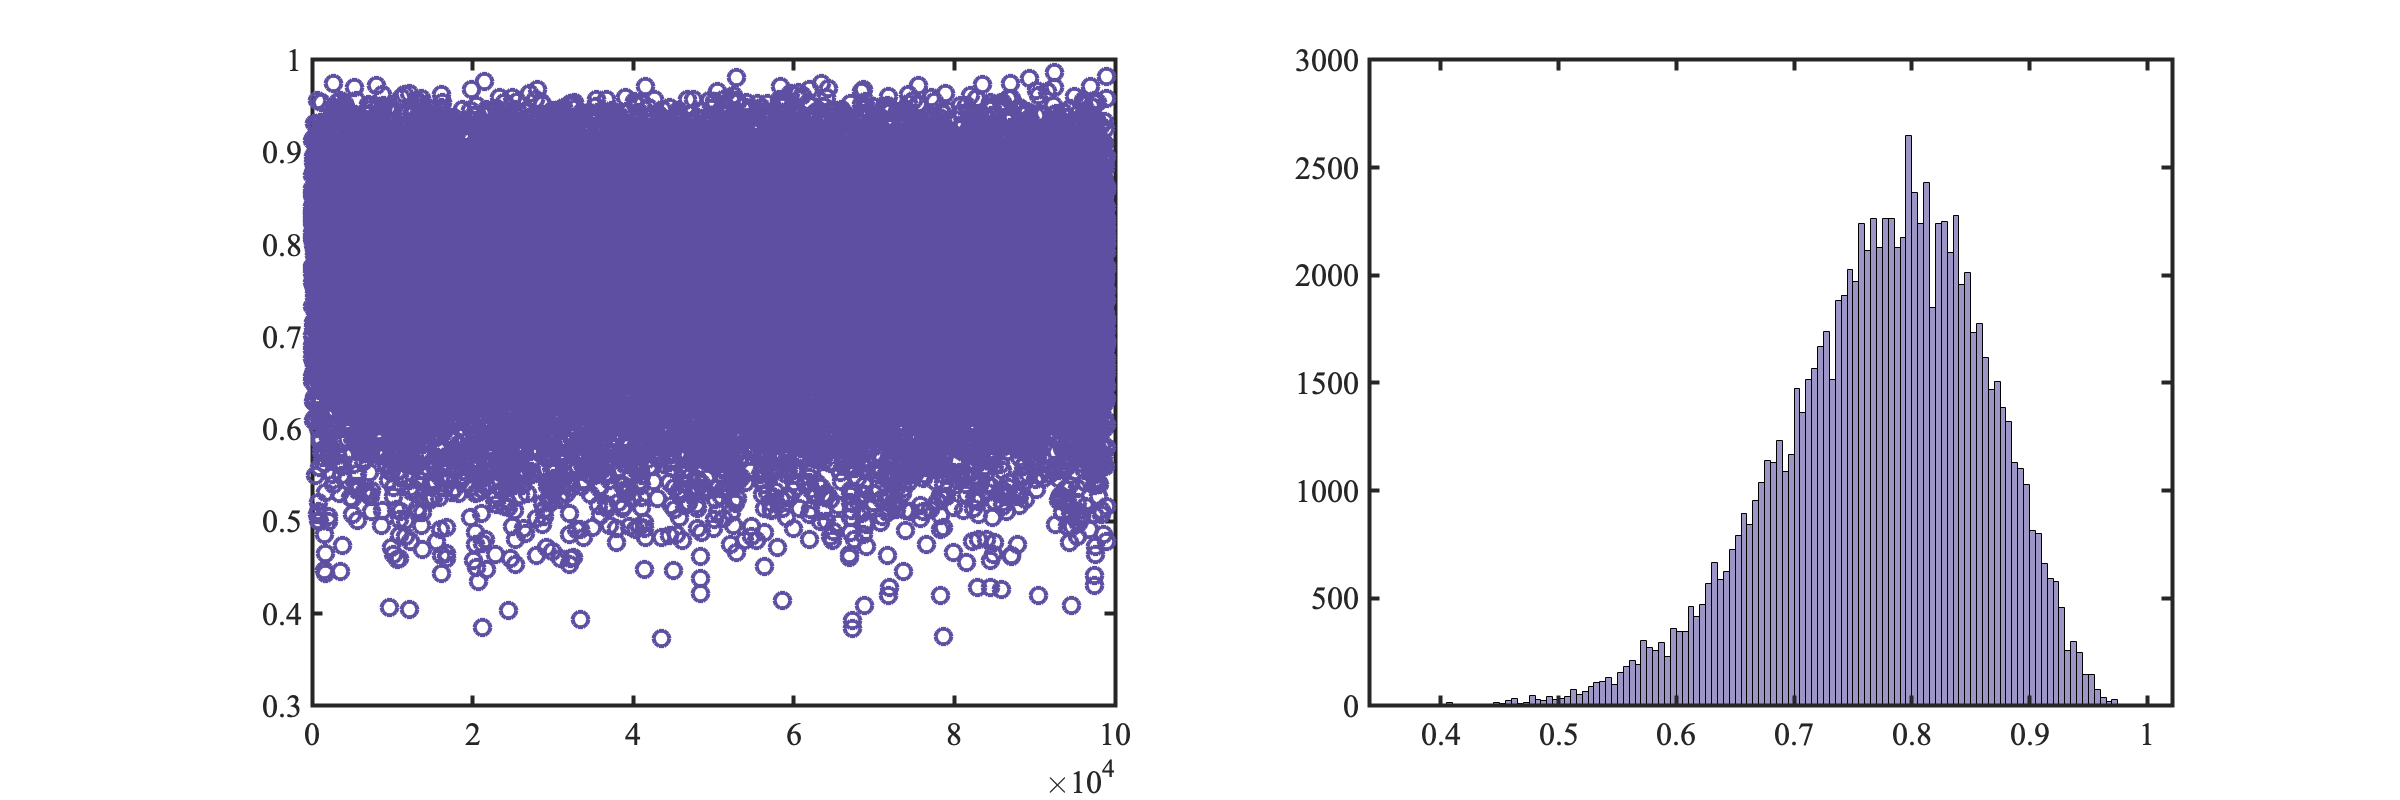


figure('position', [300 300 1200 400]);

subplot(1,2,1); 
plot(samps(burn:end), 'o', 'markersize', 8);

subplot(1,2,2);
histogram(samps(burn:end));


mode(samps(burn:end))

ans = 0.8099

## JAGS

% unsure about this, just program yourself
% help diagnostics (?)

## Local functions

function lq = log_q(w, k, n, alpha, beta)

arguments
    w (1,1) double;
    k (1,1) double = 16; 
    n (1,1) double = 20; 
    alpha (1,1) double = 1; 
    beta (1,1) double = 1; 
end

isTooLowW = w < 0;
isTooHighW = w > 1; 
if isTooLowW || isTooHighW
    lq = -inf; 
else
    lq = (k+alpha-1)*log(w)+(n-k+beta-1)*log(1-w);
end

end